# Core Tasks

## Task 1- Load and plot the MRI volumes and masks

loadData

### Visualise slice of 1st healthy and pre-eclampsia sample

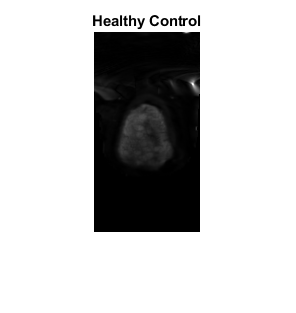

slice_of_interest = 7;
imshow(flipud(squeeze(V_healthy(:,:,slice_of_interest,1))), []);
title("Healthy Control");

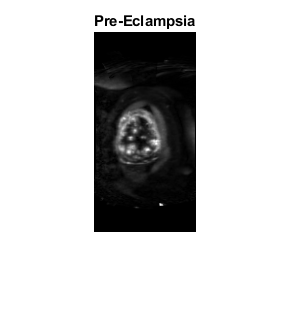

imshow(flipud(squeeze(V_pre_eclampsia(:,:,slice_of_interest,1))), []);
title("Pre-Eclampsia");

## Visualise placenta and uterine wall masks

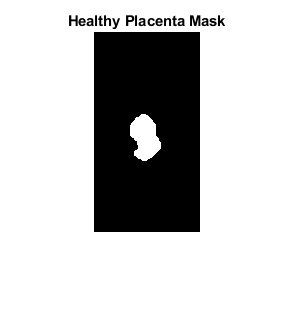

imshow(flipud(squeeze(M_healthy_placenta(:,:,slice_of_interest))), []);
title("Healthy Placenta Mask");

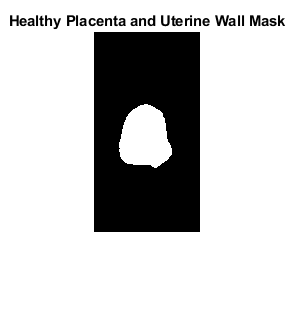

imshow(flipud(squeeze(M_healthy_placenta_uterine_wall(:,:,slice_of_interest))), []); % larger
title("Healthy Placenta and Uterine Wall Mask");

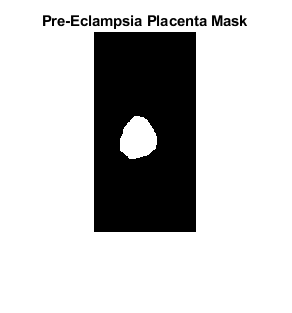

imshow(flipud(squeeze(M_pre_eclampsia_placenta(:,:,slice_of_interest))), []);
title("Pre-Eclampsia Placenta Mask");

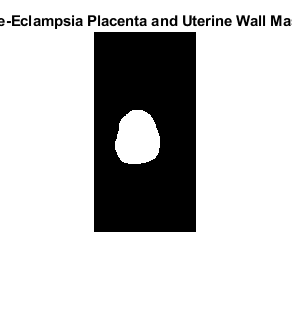

figure(4);
imshow(flipud(squeeze(M_pre_eclampsia_placenta_uterine_wall(:,:,slice_of_interest))), []);
title("Pre-Eclampsia Placenta and Uterine Wall Mask");

## Task 2- Load and plot the MRI acquisition parameters

Each row of MRI params associated with sample from volume

size(grad_echo)

ans =    330     5


size(V_healthy)

ans =    200   106    30   330


unique_b_values_number = numel(unique(grad_echo(:,4)))

unique_b_values_number = 14

unique_echo_times_number = numel(unique(grad_echo(:,5)))

unique_echo_times_number = 5

Visualise MRI params

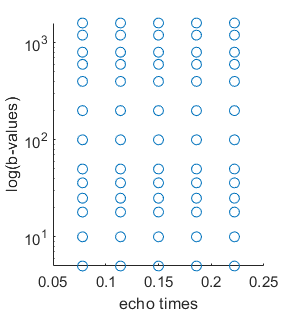

x = grad_echo(:,5);
y = grad_echo(:,4);
scatter(x,y);
set(gca, 'YScale', 'log')
xlabel("echo times");
ylabel("log(b-values)");

## Task 3- Fit combined T2*-ADC model

Init objects

model = T2ADCModel();
non_lin_optimiser = NonLinearOptimiser();

### Single voxel single run fit

Fit model to single voxel of healthy data

non_zero_voxels = reshape(nonzeros(ROI_healthy_placenta_uterine_wall), [], num_scans);
sample_voxel = non_zero_voxels(1, :)';
start_params = [100 0.01 0.001];
start_params_constr_space = T2ADCModel.to_constr_space(start_params);

[params_contr, SSD] = non_lin_optimiser.model_to_voxel(@model.predict, sample_voxel, bvals, TE, start_params_constr_space);

Print parameters

params_fitted = T2ADCModel.to_param_space(params_contr)
SSD

Visualise fit

S_predicted = model.predict(params_contr, bvals, TE);

params_fitted =   230.3268    0.0307    0.0012


figure();

SSD = 4.8936e+03

visualise_model_voxel_fit(S_predicted, sample_voxel, "Single Run")

### Constrained Single voxel multi run fit

pertubation_sigmas_constr_space = T2ADCModel.to_constr_space([50 0.01 0.001]);
[sorted_SSD, sorted_parameters] = non_lin_optimiser.multirun_exploritory(model, sample_voxel, bvals, TE, start_params_constr_space, pertubation_sigmas_constr_space);

Print model parameters

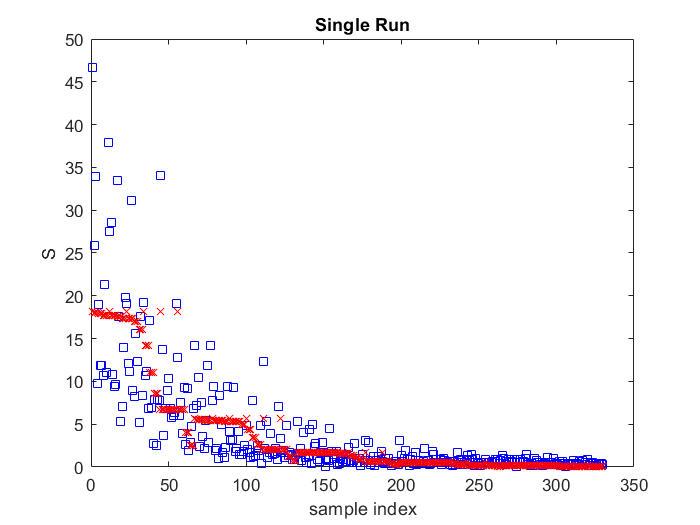

parameters = T2ADCModel.to_param_space(sorted_parameters(1, :))

SSD = sorted_SSD(1)
numRuns = num_runs_to_get_min_95_percent_time(sorted_SSD)

Visualise fit

best_fit = model.predict(sorted_parameters(1, :), bvals, TE);
visualise_model_voxel_fit(best_fit, sample_voxel, "Multi Run Constrained");

### Fit Pre Healthy Placenta with Uterine Wall (Single Slice)

Run fit

num_loops = 5; % Set based of previous experiments

parameters =   230.3256    0.0307    0.0012


[parameter_map, best_SSD_map] = non_lin_optimiser.slice_multi_run(model, slice_of_interest, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

SSD = 4.8936e+03

Visualise parameter maps

figure();

occurance_min = 0.7100

numRuns = 2.4201

plotMaps(parameter_map, best_SSD_map)

### Fit Pre Exclampsia Placenta with Uterine Wall (Single Slice)

[parameter_map, best_SSD_map] = non_lin_optimiser.slice_multi_run(model, slice_of_interest, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

Visualise parameter maps

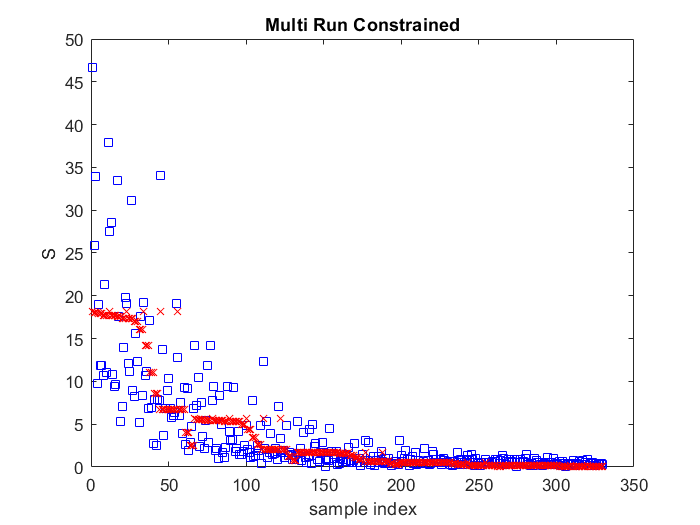

figure();

plotMaps(parameter_map, best_SSD_map)

### Fitting helper funcs

function numRuns = num_runs_to_get_min_95_percent_time(sorted_SSD)
    % Calculated as P(minumum in run) = 1-P(minimum is not in run)
    %               0.95 = 1 - (1-occurance_min)^n
    % Tolerance required as == large floating point numbers (hence high

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

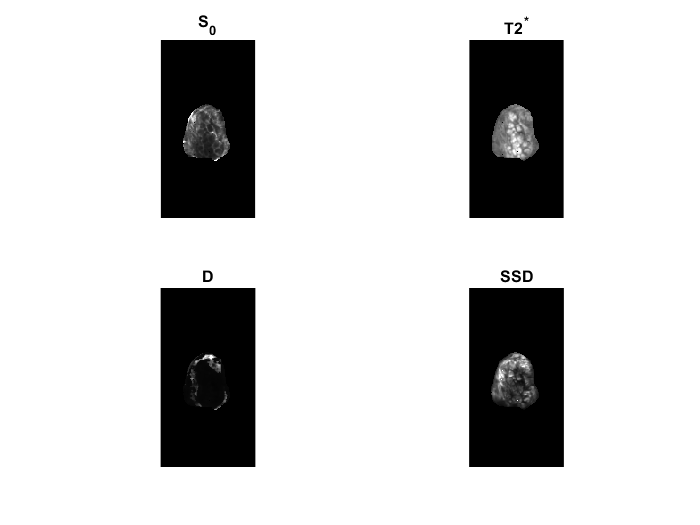

    % tolerance)
    tol = 10^-01;
    occurance_min = sum(abs(sorted_SSD-sorted_SSD(1)) < tol)/length(sorted_SSD)
    numRuns = log(0.05)/log(1-occurance_min);
end

### Plotting funcs

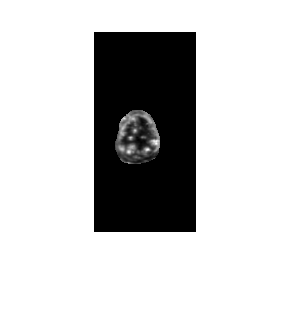

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

function visualise_model_voxel_fit(predicted, actual, plot_title)

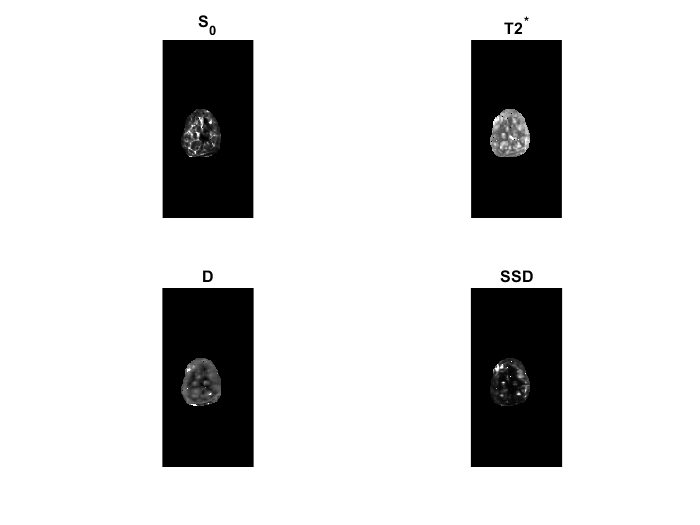

    plot(actual, ' bs')%, 'MarkerSize', 10, 'Linewidth', 4);
    hold on;
    plot(predicted, ' rx')%, 'MarkerSize', 16, 'Linewidth', 4);
    title(plot_title);
    xlabel('sample index');

    ylabel('S');
    hold off;
end

function plotMaps(parameter_map, SSD_map)
    % Plots parameters as a series of subplots
    S0 = parameter_map(1,:,:);
    T_star = parameter_map(2,:,:);
    d = parameter_map(3,:,:);
    
    plot_parameter(S0, 1, 'S_0');
    plot_parameter(T_star, 2, 'T2^*');
    plot_parameter(d, 3, 'D');
    plot_parameter(SSD_map, 4, 'SSD');
end

function plot_parameter(parameter, subplot_num, subplot_title)
    subplot(2,2,subplot_num);
    % Set upper bound as 10th highest value to handle outliers
    sorted_param = sort(parameter(:));
    imshow(flipud(squeeze(parameter)'), [0 sorted_param(end-25)]);
    title(subplot_title);
end